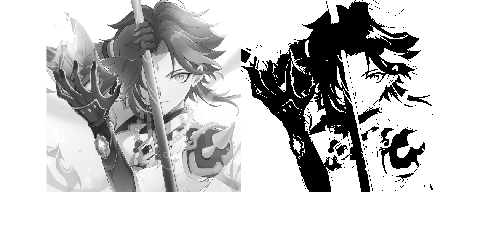

fn = "yaksha.jpg";
im = imread(fn);
img = rgb2gray(im);

imb = otsu(img);
imshowpair(img, imb, "montage");

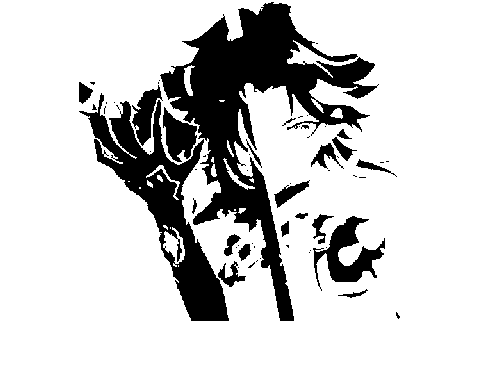

se = [0 1 0; 1 1 1; 0 1 0];

imd = dilate(imb, se);
imshow(imd);

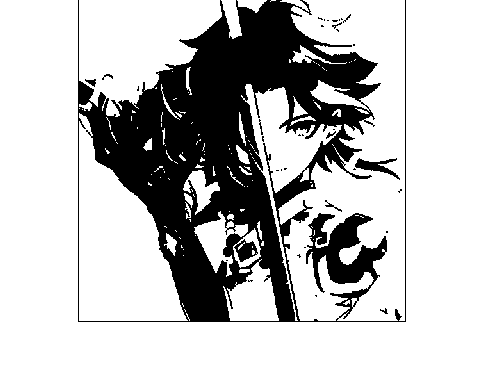


ime = erode(imb, se);
imshow(ime);

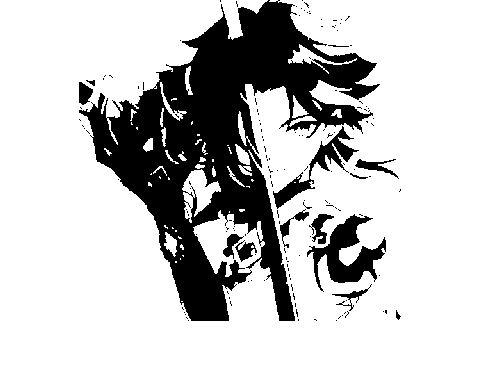

imo = openo(imb, se);
imshow(imo);

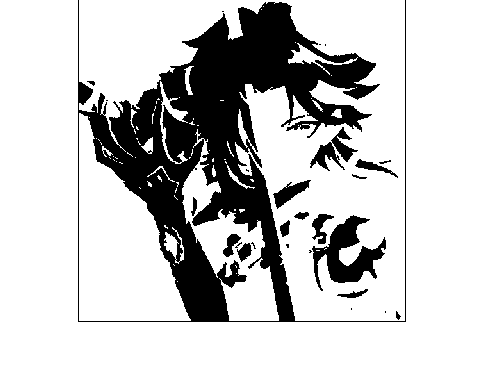


imc = closeo(imb, se);
imshow(imc);

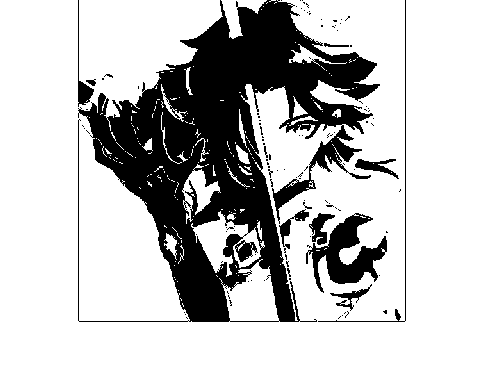

ims = bwmorph(imb, "skeleton");
imshow(ims);

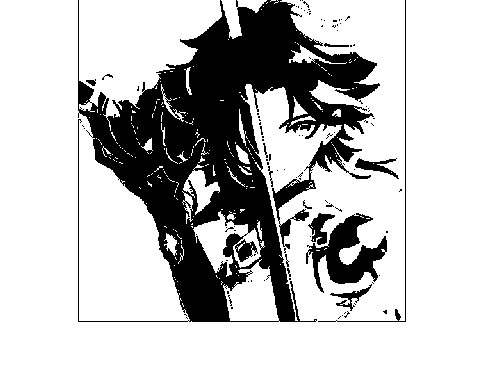


imn = bwmorph(imb, "thin");
imshow(imn);

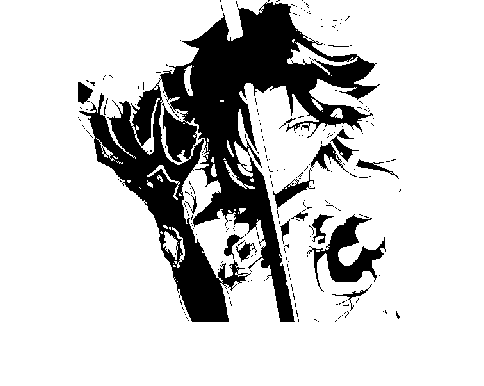


imh = bwmorph(imb, "thicken");
imshow(imh);

function ime = erode(imb, se)
    [h, w] = size(imb);
    imp = padarray(imb,[1 1],0,'both');
    ime = zeros(size(imp), 'like', imp);

    for i = 2:h+1
        for j = 2:w+1
            if isequal(imp(i-1:i+1, j-1:j+1) & se, se)
                ime(i, j) = 1;
            end
        end
    end
    ime = ime(2:end-1, 2:end-1);
end

function imd = dilate(imb, se)
    zse = zeros(size(se), 'like', se);
    [h, w] = size(imb);
    imp = padarray(imb,[1 1],1,'both');
    imd = ones(size(imp), 'like', imp);

    for i = 2:h+1
        for j = 2:w+1
            if isequal(imp(i-1:i+1, j-1:j+1) & se, zse)
                imd(i, j) = 0;
            end
        end
    end
    imd = imd(2:end-1, 2:end-1);
end

function imo = openo(imb, se)
    imo = erode(imb, se);
    imo = dilate(imo, se);
end

function imc = closeo(imb, se)
    imc = dilate(imb, se);
    imc = erode(imc, se);
end

function imb = otsu(img)
    his = tabulate(img(:));
    miu = sum(his(:, 1).*(his(:, 3)/100));
    sigm = 0;
    km = 0;
    for k = 0 : 254
        miuk = sum(his(1: k + 1, 1).*(his(1: k + 1, 3) / 100));
        omega = sum(his(1: k + 1, 3) / 100);
        sigma = (miu * omega - miuk)^2 / (omega * (1 - omega));
        if sigm < sigma
            sigm = sigma;
            km = k;
        end
    end
    imb = 0 * (img < km) + 1 * (img >= km);
end